# Modeling Respiratory Chain Dysfunction in Mitochondrial Disease 

Group 1: Ashray Kapuria, Kelsey Keith, Pratiksha Singru 

## Execute Original Model

### Model Import

modelObj = sbmlimport('model/MODEL4151491057_url.xml');

### Execute

Alter model configuration so it will run on my local machine

% get model configurations
cs = getconfigset(modelObj);

% alter model tolerances so it will run in this environment
cs.MaximumNumberOfLogs = 100;
cs.SolverOptions.AbsoluteToleranceScaling = false;

Run simulation with original parameters

% running the model results in a warning that the model generates complex
% numbers but model executes fine and we don't need to see the repeated
% warning
warning('off','all');

% run original simulation
[t, x, names] = sbiosimulate(modelObj);

Save ATP output results from original model

original = table(t, x(:,23));
original.Properties.VariableNames = ["time", "ATP"];
writetable(original, 'original_results.csv');

## Simulate Residual Complex Activity

### Get model parameters

Get original model parameters 

% get values of original parameters and save for manipulating
params = sbioselect(modelObj, 'Type', 'parameter');

% x_C1 = complex I, paramter 39
c1_orig = params(39).Value;
% x_C3 = complex III, paramter 40
c3_orig = params(40).Value;
% x_C4 = complex IV, paramter 41
c4_orig = params(41).Value;
% x_F1 = complex V, parameter 42
c5_orig = params(42).Value;

### Run model with altered parameters

All complexes will be perturbed at levels from 50% to 0% of original model activity levels

adjustments = 0:0.05:0.5;

#### Complex I

warning('off','all')

c1 = array2table(zeros(0,4));
c1.Properties.VariableNames = ["complex", "param_value", "time", "ATP"];
for l=1:length(adjustments);
    params(39).Value = c1_orig * adjustments(l);
    [t2, x2, names2] = sbiosimulate(modelObj);
    complex = repmat("Complex I", length(t2), 1);
    value = repmat(params(39).Value, length(t2), 1);
    c1temp = table(complex, value, t, x2(:,23));
    c1temp.Properties.VariableNames = ["complex", "param_value", "time", "ATP"];
    c1 = [c1; c1temp];
end

Save Results

writetable(c1, "complexI_results.csv")

#### Complex III

warning('off','all')

c3 = array2table(zeros(0,4));
c3.Properties.VariableNames = ["complex", "param_value", "time", "ATP"];
for l=1:length(adjustments);
    params(40).Value = c3_orig * adjustments(l);
    [t2, x2, names2] = sbiosimulate(modelObj);
    complex = repmat("Complex III", length(t2), 1);
    value = repmat(params(40).Value, length(t2), 1);
    c3temp = table(complex, value, t, x2(:,23));
    c3temp.Properties.VariableNames = ["complex", "param_value", "time", "ATP"];
    c3 = [c3; c3temp];
end

Save Results

writetable(c3, "complex3_results.csv")

#### Complex IV

warning('off','all')

c4 = array2table(zeros(0,4));
c4.Properties.VariableNames = ["complex", "param_value", "time", "ATP"];
for l=1:length(adjustments);
    params(41).Value = c4_orig * adjustments(l);
    [t2, x2, names2] = sbiosimulate(modelObj);
    complex = repmat("Complex IV", length(t2), 1);
    value = repmat(params(41).Value, length(t2), 1);
    c4temp = table(complex, value, t, x2(:,23));
    c4temp.Properties.VariableNames = ["complex", "param_value", "time", "ATP"];
    c4 = [c4; c4temp];
end

Save Results

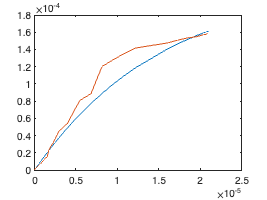

writetable(c4, "complex4_results.csv")

#### Complex V

warning('off','all')

c5 = array2table(zeros(0,4));
c5.Properties.VariableNames = ["complex", "param_value", "time", "ATP"];
for l=1:length(adjustments);
    params(42).Value = c5_orig * adjustments(l);
    [t2, x2, names2] = sbiosimulate(modelObj);
    complex = repmat("Complex V", length(t2), 1);
    value = repmat(params(42).Value, length(t2), 1);
    c5temp = table(complex, value, t, x2(:,23));
    c5temp.Properties.VariableNames = ["complex", "param_value", "time", "ATP"];
    c5 = [c5; c5temp];
end

Save Results

writetable(c4, "complex4_results.csv")

## Simulation Results

Please see `../figures/figures.Rmd` for the code for result plots, tables, and sensitivity calculations.